# Homework 10 Problem 13.1

clear; close; clc;


## Inexact stepsize test

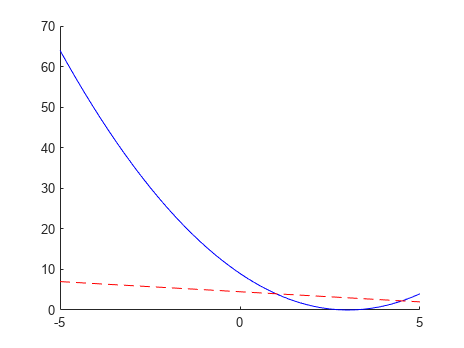

figure; 
hold on; 
x_0 = 1; 
fplot(@(x)(x-3).^2,"-b"); 
fplot(@(x) (x_0-3).^2-.5*(x-x_0),"--r"); 

x_0 + inexactStepSize(1, 1, @(x) (x-2)^2, .5, .5)

ans = 2

## Declaration and Initialization

% solver parameters
epsilon_1 = 1e-6; % unconstrained tolerance
epsilon_2 = 1e-6; % near constraint tolerance
R = 1; % initial value for penalty parameter
gamma = .5; % parameter for inexact line search (range [0,1])
mu = .5;
max_iterations = 10000; % maximum number of itterations until program termination (10000 for my anealing studies)
H = eye(2); % Hessian to be used in quadratic subproblem (set to Identity for CSD)

% initial condition
x = [500; 700]; % initial values for b and d repsectively
%x = [450; 800]

% constraints
lower_bounds = [10, 10]; % lower bounds on b,d
upper_bounds = [1e4,1e4]; % upper bounds on b,d

% loop vairables
k = 0; % itteration number

% cooling parameters
T_0 = 100; % initial temperature (.1 works for my log function) (100 for linear) (1000 for inverse) (100 for clasic exponential)
T_F = 0;
Freeze_time = max_iterations - 1000; % itteration at which it freezes (100 works for my log function) (1000 for linear and inverse)
beta = .9;

%plotting parameters
x_limits = [0,1000];
y_limits = [0,1000];

% Matrices to store values
x_hist = zeros([length(x), max_iterations]); % design variable values
d_hist = zeros([length(x), max_iterations]); % step sizes
f_hist = zeros([1, max_iterations]); % function values
alpha_hist = zeros([1, max_iterations]); % step sizes
R_hist = zeros([1, max_iterations]); % Penalty parameters
T_hist = zeros([1, max_iterations]); % Temperature

% TODO store initial values

## Optimizer


% CSD algorithm:
%   obtain quadratic subproblem f_tilde = c.T d + 1/2 d.T d
%   solve quadriatic subproblem -> alpha, LM
%   obtain descent function
%   minimize descent function -> step size
%   update design


% what I will do:

% find important vlaues @ current x ( c, g, grad(g), h, grad(h), v )
% solve QP subproblem
% check convergence
% Select R_next
% solve step size (inexact line search)
% update design

options = optimoptions('quadprog', 'Display', 'off'); % prepare options for quadprog

g= Inf; % initialize g to inf to ensure first itteration of loop runs 

while k < max_iterations && (any(g > epsilon_1) || norm(d) > epsilon_2)
    % find important vlaues @ current x ( c, g, grad(g), h, grad(h), v )
    [f, c] = objective_Function(x); % cost func vlaue and cost fun gradient
    [g, A] = inequalConstraintFunction(x); % ineqality contraint value and inequality contraint gradient
    
    % store values of variables
    x_hist(:,k+1) = x;
    f_hist(k+1) = f;

    % solve QP sub prooblem
    % Takes:  function handle, cost; function handle equlaity constraints; function handle inequlaity constraints
    % use quad prog
    b = -g; % negative contraint values
    [d, ~, exitflag, ~, lambda] = quadprog(H, c, A, b, [], [], [], [], [], options); % solves the quadratic progrmming problem at design point using provided values of hessian, cost gradient, contraint gradient matrix, and negative contraint values

%     disp("is descent direction: " +(dot(c,d)<=0))
%     disp("is current point feasible: " +all(g>=epsilon_1))

    % check that convergence was obtained
    if exitflag < 1 % did solution converge?
        % alert user and fail gracefully
        %error("Quadratic subproblem failued to converge on itteration %g. exit flag: %g", k, exitflag);
        warning("Quadratic subproblem failued to converge on itteration %g. exit flag: %g", k, exitflag);

    end

    
    % lagrange multipiers of solution
    v = lambda.eqlin; % linear equality contraint lagrange multipliers -> rewrite to include if relevant
    u = lambda.ineqlin; % linear inequality contraint lagrange multipliers
    
    % compute descent function:
    [phi, R] = DescentFunction(x, R, @(x)inequalConstraintFunction(x), @(x)objective_Function(x), u, v);
    
    % solve step size:
    alpha = inexactStepSize(x, d, phi, gamma, mu);
    %alpha = golden_search(phi, x, d, 1e-5);
    %alpha = 1

    % print output
%     k
%     x
%     f
%     R
%     d
%     alpha

    % create the random vector
    rand_vect = [-1+2*rand(1,1); -1+2*rand(1,1)];

    % custom cooling profiles
    %T = T_0/(k+1); % magiutude of random vector ( staets at k+1 to avoid inf)
    %T = max(0,(T_0-T_F)/Freeze_time * (Freeze_time-k)); % linear
    %T = max(0, T_0/log(k+2) - (k+1 - Freeze_time + T_0/log(Freeze_time+2))); % log
    
    %classic cooling profiles
    T = max(T_0 - beta*k, 0); % linear (T_0 = 100; beta = .5)
    T = max(T_0 * beta^k, 0); % exponential (T_0 = 100; beta = .99)
    %T = max(T_0 / log(2+k), 0); % logarithmic (T_0 = 10-50; max_iterations = 10000)

    if(k > Freeze_time) % should we stop the gloabal search and try to find local?
        T=0; % stop the random perterbations devolve to steepest descent
    end

    % update design
    x = x + alpha*d + T*rand_vect;
    %x = x + alpha*d;
    k = k+1;

    % updates stored variables
    d_hist(:,k+1) = d;
    alpha_hist(k+1) = alpha;
    T_hist(k+1) = T;

    % attempt to fix issue with excesive penalty paramter growth (lazy solution)
%     if all(g <= epsilon_1)
%         R = 100*T; % this relating R to T if in a feasible region works quite well
%     end
end
disp("done")

done



%figure
%plot(x_hist)

## Plot


% Create a grid of points
xSpace = linspace(x_limits(1), x_limits(2), 400);
ySpace = linspace(y_limits(1), y_limits(2), 400);
[X, Y] = meshgrid(xSpace, ySpace);

% Evaluate the objective function on the grid
Z = arrayfun(@(x,y) objective_Function([x;y]), X,Y);

% Define the functions
g1 = @(x, y) 2.4e8 ./ (x .* y.^2) - 10;
g2 = @(x, y) 4.5e5 / (2 * x * y) - 2;
g3 = @(x, y) y - 2 * x;


figure;
%%Create two axes
ax1 = axes;
set(gca,"Color",[0.5,0.5,0.5])
% plot f
contourf(X, Y, Z, 50, "-", "EdgeColor","none");
hold on
% Plot g1
fimplicit(@(x, y) g1(x, y), [x_limits, y_limits], 'r', "LineWidth",2);

% Plot g2
fimplicit(@(x, y) g2(x, y), [x_limits, y_limits], 'g', "LineWidth",2);


% Plot g3
fimplicit(@(x, y) g3(x, y), [x_limits, y_limits], 'b', "LineWidth",2);

% Add labels and title
xlabel('x');
ylabel('y');
title('Iteration History');
legend('f','g1', 'g2', 'g3','convergence history');

grid on;
view(2)
ax2 = axes;
patch([x_hist(1,1:k), nan], [x_hist(2,1:k), nan], [1:k, nan], 'EdgeColor', 'interp', 'Marker', 'o', 'MarkerFaceColor', 'flat', 'LineWidth', 2, 'FaceColor', 'none'); colormap(flipud(hot)); %colormap(ax2,flipud(hot))
%patch([x_hist(1,1:k), nan], [x_hist(2,1:k), nan], [T_hist(1:k), nan], 'EdgeColor', 'interp', 'Marker', 'o', 'MarkerFaceColor', 'flat', 'LineWidth', 2, 'FaceColor', 'none'); colormap(ax2,hot);

%%Link them together
linkaxes([ax1,ax2])

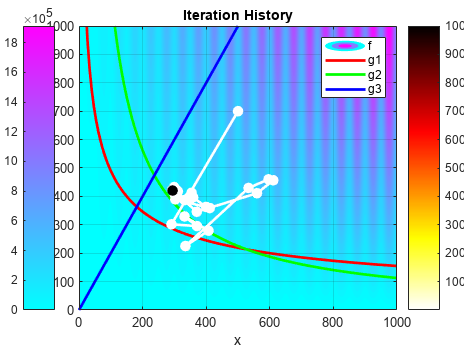

%%Hide the top axes
ax2.Visible = 'off';
ax2.XTick = [];
ax2.YTick = [];
%%Give each one its own colormap
colormap(ax1,'cool')
colormap(ax2,flipud(hot))
%%Then add colorbars and get everything lined up
set([ax1,ax2],'Position',[.17 .11 .685 .815]);
set([ax1,ax2],'Color',[.5,.5,.5]);
cb1 = colorbar(ax1,'Position',[.05 .11 .0675 .815]);
cb2 = colorbar(ax2,'Position',[.88 .11 .0675 .815]);


% write the outputs

% simulated anealing
fprintf("simulated anealing minimum f = %.5g, at x_1 = %.5g, x_2 = %.5g", f, x(1), x(2))

simulated anealing minimum f = 1.3915e+05, at x_1 = 294.27, x_2 = 420.7


% simulated anealing history search
Filt = (2.4e8 ./ ( x_hist(1,:) .* x_hist(2,:).^2 ) - 10<=0) & (4.5e5 ./ ( 2 * x_hist(1,:) .* x_hist(2,:)) - 2<=0) & (x_hist(2,:)- 2*x_hist(1,:)<=0);
[hist_min, hist_min_index] = min(f_hist(Filt));
x_hist_min = x_hist(1,hist_min_index);
y_hist_min = x_hist(2,hist_min_index);
%fprintf("historical minimum f = %.5g, at x_1 = %.5g, x_2 = %.5g", hist_min, x_hist_min, y_hist_min)
%disp("is historical min a feasible point: " + all(inequalConstraintFunction([x_hist_min,y_hist_min])<=epsilon_1))
%disp("beware historical min can be slightly optimistic sometimes - should still CSD from min")

% monte carlo
G1 = 2.4e8 ./ ( X .* Y.^2 ) - 10<=0;
G2 = 4.5e5 ./ ( 2 * X .* Y) - 2<=0;
G3 = Y- 2*X<=0;
Filter = (G1 & G2 & G3);
[monte_carlo_min, min_linear_index] = min(Z(Filter)); % mind min of f in feasible region

X_filt = X(Filter); Y_filt = Y(Filter); % filter x and y value to only include feasible region
x_min = X_filt(min_linear_index);
y_min = Y_filt(min_linear_index);
fprintf("monte carlo minimum f = %.5g, at x_1 = %.5g, x_2 = %.5g", monte_carlo_min, x_min, y_min)

monte carlo minimum f = 1.129e+05, at x_1 = 350.88, x_2 = 320.8

function [f, c] = objective_Function(x)
    f = x(1,:) * (sin(x(1,:)/100*(2*pi)).^2 + 1) .*x(2,:); % cost function
    c = [x(2,:), x(1,:)]/100; % const function gradient
    c = 100*[(x(2,:)*(sin((pi*x(1,:))/50)^2 + 1))/100 + (pi*x(1,:)*x(2,:)*cos((pi*x(1,:))/50)*sin((pi*x(1,:))/50))/2500, (x(2,:)*(sin((pi*x(1,:))/50)^2 + 1))/100 + (pi*x(1,:)*x(2,:)*cos((pi*x(1,:))/50)*sin((pi*x(1,:))/50))/2500];
end

function [g, A] = inequalConstraintFunction(x)
    g = zeros([3,1]); % initialize g

    % assign values to constraints
    g(1) = 2.4e8 / ( x(1) * x(2)^2 ) - 10;
    g(2) = 4.5e5 / ( 2 * x(1) * x(2)) - 2;
    g(3) = x(2) - 2*x(1); % this contraint may need to be normalized (mult by .5)

    

    % compute gradient of contraints
    A = [
        -2.4e8 / (x(1)^2 * x(2)^2)  , -4.8e8 / (2 *x(1) * x(2)^3) ; % partials of g_1
        -4.5e5 / (2*x(1)^2 * x(2))  , -4.5e5 / (2*x(1) * x(2)^2)  ; % partials of g_2
        -2                          , 1                             % partials of g_3
        ];

    % normalized
    % assign values to constraints
%     g(1) = (2.4e8 / ( x(1) * x(2)^2 ) - 10)/10;
%     g(2) = (4.5e5 / ( 2 * x(1) * x(2)) - 2) *10;
%     g(3) = (x(2) - 2*x(1))/200; % this contraint may need to be normalized (mult by .5)
%     % compute gradient of contraints
%     A = [
%         -2.4e8 / (x(1)^2 * x(2)^2) / 10  , -4.8e8 / (2 *x(1) * x(2)^3) / 10 ; % partials of g_1
%         -4.5e5 / (2*x(1)^2 * x(2)) *10  , -4.5e5 / (2*x(1) * x(2)^2) *10 ; % partials of g_2
%         -2/200                          , 1/200                             % partials of g_3
%         ];

%     % with non neg
%     % assign values to constraints
%     g(1) = 2.4e8 / ( x(1) * x(2)^2 ) - 10;
%     g(2) = 4.5e5 / ( 2 * x(1) * x(2)) - 2;
%     g(3) = x(2) - 2*x(1); % this contraint may need to be normalized (mult by .5)
%     g(4) = -x(1);
%     g(5) = -x(2);
% 
%     A = [
%         -2.4e8 / (x(1)^2 * x(2)^2)  , -4.8e8 / (2 *x(1) * x(2)^3) ; % partials of g_1
%         -4.5e5 / (2*x(1)^2 * x(2))  , -4.5e5 / (2*x(1) * x(2)^2)  ; % partials of g_2
%         -2                          , 1                             % partials of g_3
%         -1                          , 0                             % partials of g_3
%         -0                          , -1                             % partials of g_3
%         ];

    % normalizedwith non neg
    % assign values to constraints
    g(1) = (2.4e8 / ( x(1) * x(2)^2 ) - 10)/10;
    g(2) = (4.5e5 / ( 2 * x(1) * x(2)) - 2) *10;
    g(3) = (x(2) - 2*x(1))/200; % this contraint may need to be normalized (mult by .5)
    g(4) = -x(1);
    g(5) = -x(2);

    A = [
        -2.4e8 / (x(1)^2 * x(2)^2) / 10  , -4.8e8 / (2 *x(1) * x(2)^3) / 10 ; % partials of g_1
        -4.5e5 / (2*x(1)^2 * x(2)) *10  , -4.5e5 / (2*x(1) * x(2)^2) *10 ; % partials of g_2
        -2/200                          , 1/200                             % partials of g_3
        -1                          , 0                             % partials of g_3
        -0                          , -1                             % partials of g_3
        ];

end
